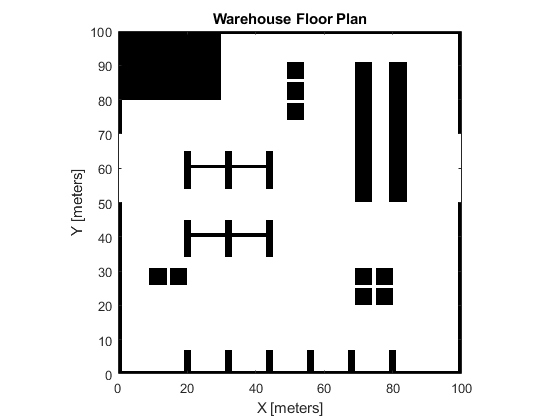

% Create warehouse binary occupancy map
map = binaryOccupancyMap(100, 100, 1);
occ = zeros(100, 100);

% map boundaries
occ(1,:) = 1;
occ(end,:) = 1;
occ([1:30, 51:100],1) = 1;
occ([1:30, 51:100],end) = 1;

% boxes
occ(10:14,50:54) = 1;
occ(16:20,50:54) = 1;
occ(22:26,50:54) = 1;
occ(10:14,50:54) = 1;

occ(70:74,10:14) = 1;
occ(70:74,16:20) = 1;

occ(70:74,70:74) = 1;
occ(70:74,76:80) = 1;
occ(76:80,70:74) = 1;
occ(76:80,76:80) = 1;

% vertical conveyer belts
occ(10:50,80:84) = 1;
occ(10:50,70:74) = 1;

% shelves
occ(40,20:44) = 1;
occ(36:46,[20:21 32:33 44:45]) = 1;
occ(60,20:44) = 1;
occ(56:66,[20:21 32:33 44:45]) = 1;
occ(1:20, [1:30]) = 1;

% bottom shelves
occ(end-6:end, [20:21 32:33 44:45 56:57 68:69 80:81]) = 1;

setOccupancy(map, occ)
figure
show(map)
title('Warehouse Floor Plan')

branching = 8;
pad = 24;

%should inflate radius
maze = occupancyMatrix(map);

% Create a new Hybrid A* Planner
estMap = occupancyMap(occupancyMatrix(map));
ss = stateSpaceSE2;
ss.StateBounds = [estMap.XWorldLimits; estMap.YWorldLimits; [-pi pi]];
vMap = validatorOccupancyMap(ss);
vMap.Map = estMap;
vMap.ValidationDistance = 0.5;
planner = plannerHybridAStar(vMap, 'MinTurningRadius', 1.3);

startPose = [90 90 pi/2];
boxPose = [20 50 -pi];
goalPose = [5 5 pi/2];

%need to be able to index to each path

route1 = plan(planner, startPose, boxPose);
route2 = plan(planner, boxPose, goalPose);
waypoints1 = [];
waypoints2 = [];

for i=1:height(route1.States)
    if mod(i+4,5) == 0 waypoints1 = [waypoints1; route1.States(i,:)]; end
end

n_box = size(waypoints1,1);

for i=1:height(route2.States)
    if mod(i+4,5) == 0 waypoints2 = [waypoints2; route2.States(i,:)]; end
end

size2 = size(waypoints2,1);
waypoints = [waypoints1; waypoints2];
lastwpt = waypoints(size(waypoints,1),:);
waypoints = [waypoints; lastwypt];

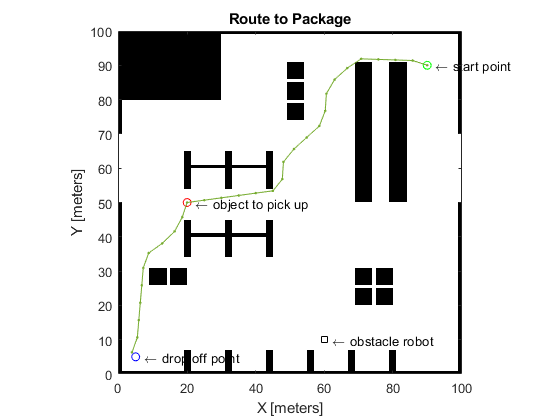

% Make disc robot obstacles
disc1StartPose = [60,10,pi/2];

% Plot initial waypoints on map
figure
show(map); hold on
plot(startPose(1), startPose(2), 'go')
text(startPose(1), startPose(2), '  \leftarrow start point')
plot(boxPose(1), boxPose(2), 'ro')
text(boxPose(1), boxPose(2), '  \leftarrow object to pick up')
plot(goalPose(1), goalPose(2), 'bo')
text(goalPose(1), goalPose(2), '  \leftarrow drop off point')
plot(disc1StartPose(1), disc1StartPose(2), 'ks')
text(disc1StartPose(1), disc1StartPose(2), '  \leftarrow obstacle robot')
plot(waypoints(:,1), waypoints(:,2), '.-'); hold off
title('Route to Package')

% Rescale poses and waypoints by factor of 5 for simulation
warning('off','all')

waypoints(:,1:2) = waypoints(:,1:2)/5;
startPose = [18 18 pi/2];
boxPose = [4 10 -pi];
goalPose = [1 1 pi/2];
disc1StartPose = [12 2 pi/2];
resolution = 5;
Tf = 100;

simulation = sim("clawbot_planner.slx", [0 Tf])

p =
     1



ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

ans =
   1

arm_pose =
    15

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     0

omega =
     0

v =
     

simulation =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [30117x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



% Plot robot trajectory
[time, state, stateDot] = extractSimOutHelper(simulation, Tf);
figure, plotWPHelperFunction(startPose, goalPose, boxPose, state, stateDot);

Helper Functions

function [time, state, stateDot] = extractSimOutHelper(simout, Tf)
    time = linspace(0, Tf, length(simout.yout{1}.Values.Data(:,1)));
    state = simout.yout{1}.Values.Data;
    stateDot = simout.yout{2}.Values.Data;
end

function plotWPHelperFunction(startPose, goalPose, boxPose, state, stateDot)
    res = 5; 
    v = sqrt(stateDot(:,1).^2 + stateDot(:,2).^2);
    
    scatter(state(1:res:end,1), state(1:res:end,2), 20, v(1:res:end), "filled","s","MarkerEdgeColor",'k'), hold on, 
    
    % start pose
    scatter(startPose(1), startPose(2), 80, "green","filled","MarkerEdgeColor",'k')
    
    % box location
    scatter(boxPose(1), boxPose(2), 80, "red","filled","MarkerEdgeColor",'k')
    
    % goal pose
    scatter(goalPose(1), goalPose(2) , 80, "blue", "filled","MarkerEdgeColor",'k')
    
    % end pose
    scatter(state(end,1), state(end,2), 120, "blue", "filled","x","MarkerEdgeColor",'k')
    
    % labels
    xlabel 'x (m)'
    ylabel 'y (m)'
    legend('path', 'start', 'goal', 'end')
    legend box off
    legend Location best
    box on
    cb = colorbar;
    cb.Title.String = 'v (m/s)';
end